**ESERCITAZIONE 1 - PARTE 1**

Lo scopo di questo script è quello di simulare la costruzione di un dataset.

Supponiamo di osservare tre fenomeni distinti, i quali si manifestano casualmente uno dopo l'altro e decidiamo di scrivere in una tabella, ogni volta, i valori di tre differenti parametri che misuriamo da ogni fenomeno ad ogni loro manifestazione.

In questo modo andremo a costruire un dataset con tante righe quante sono le manifestazioni dei fenomeni (osservazioni, in generale N), tante colonne quanti sono i parametri analizzati (feature, in questo caso 3) e tanti differenti valori di etichette quanti sono i fenomeni distinti osservati (classi, in questo caso sempre 3).

Procedere quindi codificando i seguenti passi:

**1)** Supponiamo che i fenomeni siano tutti di tipo aleatorio e che i parametri che andiamo a misurare abbiano quindi tutti una distribuzione ad esempio Normale; definire allora ogni fenomeno attraverso una sua media (in 3 dimensioni, una per feature, quindi un vettore 1x3) ed una sua varianza (una matrice di covarianza 3x3, simmetrica)

% Fenomeno 1
mu_1 = [3 15 9]

mu_1 =      3    15     9


sigma_1 =     1.0000    0.5000         0
    0.5000    1.0000         0
         0         0    1.0000


mu_2 =     12     9     3


sigma_2 =      1     0     0
     0     2     0
     0     0     1


mu_3 =      6     3    15


sigma_3 =      3     0     0
     0     1     0
     0     0     1


sigma_1 = [1 .5 0
           .5 1 0
           0 0 1]

% Fenomeno 2
mu_2 = [12 9 3]
sigma_2 = [1 0 0
           0 2 0
           0 0 1]

% Fenomeno 3
mu_3 = [6 3 15]
sigma_3 = [3 0 0
           0 1 0
           0 0 1]

 media di ogni fenomeno sarà il centro di aggregazione delle osservazioni del fenomeno stesso, mentre la matrice di covarianza determinerà la dispersione delle sue osservazioni.

**2)** Dobbiamo ora simulare l'osservazione dei fenomeni e la raccolta dei relativi dati misurati.

- Creare una matrice di dataset vuota;

- Creare un ciclo di N osservazioni a scelta (es. 100);

- Per ogni iterazione scegliere casualmente uno dei tre fenomeni (attraverso una varabile che potrà valere casualmente 1 o 2 o 3);

- Generare 3 valori casuali (uno per parametro misurato) con distribuzione Normale provenienti dal tipo fenomeno casualmente scelto (consiglio: usare la funzione "mvnrnd()");

- Aggiungere in coda al dataset i valori generati assieme al tipo di fenomeno che li ha generati.

% Acquisizione del dataset
Nobs = 100;     % Numero di osservazioni che facciamo

dataset = [];
for i = 1:Nobs
    scelta = rand;       % "scelta" indica la casualità della scelta del fenomeno che si manifesta
    if scelta <= 0.3
        obs = mvnrnd(mu_1, sigma_1);    % "mvnrnd()" genera un valore casuale suguendo una Normale Multivariata con specifica media e matrice di covarianza
        c = 1;      % "c" indica la classe di appartenenza del fenomeno
    elseif scelta <= 0.8
        obs = mvnrnd(mu_2, sigma_2);
        c = 2;
    else
        obs = mvnrnd(mu_3, sigma_3);
        c = 3;
    end
    
    dataset = cat(1, dataset, [obs c]);     % scrivo l'osservazione nel dataset: le feature misurate e l'etichetta del fenomeno associato
end
dataset

dataset =     6.7823    2.5597   14.8301    3.0000
    5.0365   15.1665    8.0217    1.0000
    5.2758    2.5760   15.4364    3.0000
    3.7777   14.4105   10.2128    1.0000
    5.6902    4.4273   15.3520    3.0000
   13.0126   11.7062    4.4472    2.0000
    2.7271    1.5748   15.5386    3.0000
    6.5498    1.9217   16.4706    3.0000
    5.6000    3.8277   14.6675    3.0000
   12.3022    8.3601    1.1933    2.0000


Ora dovremmo avere un dataset numerico di dimensioni Nx(M + 1).

**3)** Plottare il dataset mostrando ogni osservazione come un punto distinto ed evidenziandolo con un colore specifico della classe classe di appartenenza: in questo modo andremo a vedere come si distribuiscono i valori registrati nello spazio delle feature (essendo 3 le feature del dataset, avremo uno spazio 3D).

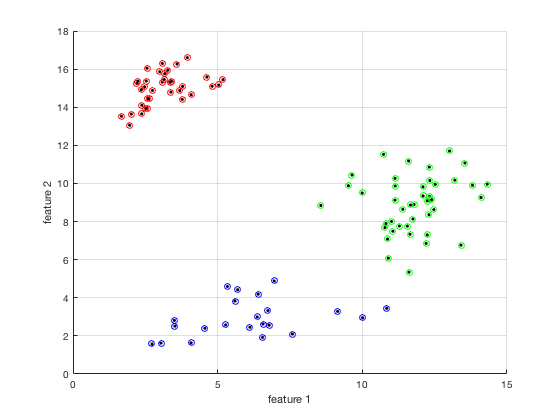

% Plot delle osservazioni nello spazio delle feature
cla
scatter3(dataset(:, 1), dataset(:, 2), dataset(:, 3), 'k.')     % disegno tutte le osservazioni alle coordinate delle relative feature
hold on

class_1_map = dataset(:, end) == 1;     % seleziono le osservazioni del fenomeno 1
scatter3(dataset(class_1_map, 1), dataset(class_1_map, 2), dataset(class_1_map, 3), 'ro')       % evidenzio le osservazioni selezionate di rosso

class_2_map = dataset(:, end) == 2;
scatter3(dataset(class_2_map, 1), dataset(class_2_map, 2), dataset(class_2_map, 3), 'go')

class_3_map = dataset(:, end) == 3;
scatter3(dataset(class_3_map, 1), dataset(class_3_map, 2), dataset(class_3_map, 3), 'bo')

xlabel('feature 1')     % scrivo il nome delle feature sugli assi
ylabel('feature 2')
zlabel('feature 3')

Dal plot si vedono i tre fenomeni distinti, centrati nelle loro medie e con una ellitticità determinata dalle relative matrici di covarianza. Avere un dataset come questo è generalmente l'inizio di una pipeline di Machine Learning classico.